17.15

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
pid.Kp = 0.472;
pid.Kd = 0.016;
pid.Tl = 0.004;
wc = 2 * pi * 5;
dl = 1 / sqrt(2);
wn = 2 * pi * 10;
Ts = 0.01;
bit = 10;
umax = 10;
res = 2000;
pulse2deg = 360 / res;
deg2pulse = res / 360;
rad2deg = 180 / pi;
deg2rad = pi / 180;
rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);

s = tf('s');
Pc = mot.k / (s * (mot.T * s + 1));
[numPc, denPc] = tfdata(Pc, 'v');
Pn = c2d(Pc, Ts, "zoh");

z = tf('z', Ts);
s = (1 - z^-1) / Ts;
C = minreal(pid.Kp + pid.Kd * s / (pid.Tl * s + 1), 1e-6);
[numC, denC] = tfdata(C, 'v');
H = minreal(wc^2 * s / (s^2 + 2 * dl * wc * s + wc^2), 1e-6);
[numH, denH] = tfdata(H, 'v');

s = (z - 1) / Ts;
Q = minreal(wn^2 / (s^2 + 2 * dl * wn * s + wn^2), 1e-6);
[numQ, denQ] = tfdata(Q, 'v');
[numQP, denQP] = tfdata(minreal(Q / Pn, 1e-6), 'v');

r.A = 250;
r.t = 0;
d.A = 5;
d.t = 1;

open_system("ex3_sim1m.slx")

set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "2")
sim("ex3_sim1m")

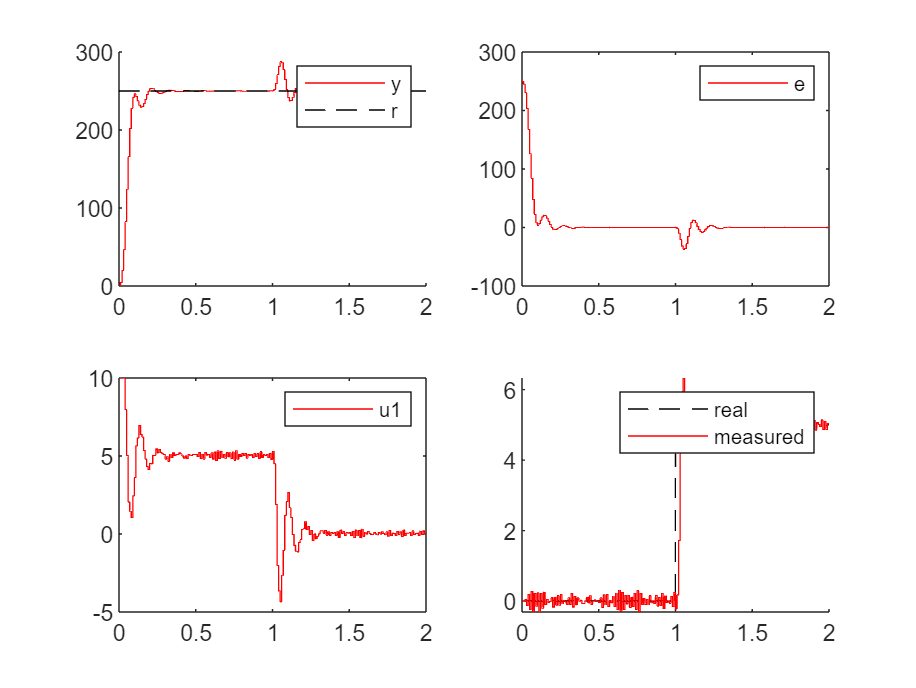

close all
figure(1)
subplot(2, 2, 1)
hold on
plot(sim1_res.time, sim1_res.signals(1).values, "r")
plot(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("y", "r")
subplot(2, 2, 2)
plot(sim1_res.time, sim1_res.signals(3).values, "r")
legend("e")
subplot(2, 2, 3)
plot(sim1_res.time, sim1_res.signals(4).values, "r")
legend("u1")
subplot(2, 2, 4)
hold on
plot(sim1_res.time, sim1_res.signals(5).values, "k--")
plot(sim1_res.time, sim1_res.signals(6).values, "r")
legend("real", "measured")